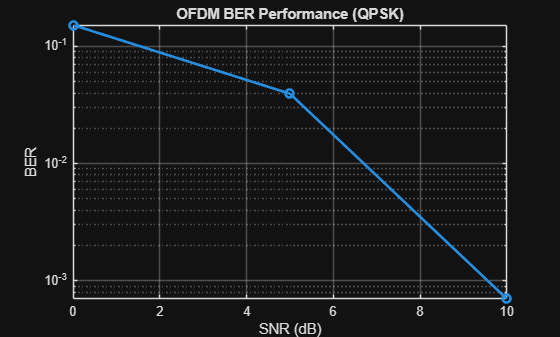

clc;
clear;
close all;

%% ----------------------------------
% PARAMETERS
%% ----------------------------------
N = 1e4;           % number of bits
M = 4;             % QPSK
k = log2(M);       

Nsc = 64;          % subcarriers
cp_len = 16;       
SNR_dB = 0:5:20;

BER = zeros(size(SNR_dB));

%% ----------------------------------
% LOOP OVER SNR
%% ----------------------------------
for snr_idx = 1:length(SNR_dB)

    %% ------------------------------
    % 1. Bit Generation (SAFE)
    %% ------------------------------
    bits = randi([0 1], 1, N);

    % Ensure divisible by k
    bits = bits(1:floor(length(bits)/k)*k);

    %% ------------------------------
    % 2. QAM Mapping
    %% ------------------------------
    symbols = bi2de(reshape(bits, k, []).', 'left-msb');
    mod_data = qammod(symbols, M, 'UnitAveragePower', true);

    %% ------------------------------
    % 3. Serial to Parallel (SAFE FIX)
    %% ------------------------------
    num_ofdm_symbols = floor(length(mod_data)/Nsc);

    % Trim extra data
    mod_data = mod_data(1:num_ofdm_symbols*Nsc);

    % Now reshape safely
    mod_data = reshape(mod_data, Nsc, num_ofdm_symbols);

    %% ------------------------------
    % 4. IFFT (OFDM Modulation)
    %% ------------------------------
    tx_ifft = ifft(mod_data, Nsc);

    %% ------------------------------
    % 5. Add Cyclic Prefix
    %% ------------------------------
    tx_cp = [tx_ifft(end-cp_len+1:end, :); tx_ifft];

    %% ------------------------------
    % 6. Serialize
    %% ------------------------------
    tx_signal = tx_cp(:).';

    %% ------------------------------
    % 7. Channel (AWGN)
    %% ------------------------------
    rx_signal = awgn(tx_signal, SNR_dB(snr_idx), 'measured');

    %% ------------------------------
    % 8. Receiver: Parallelization
    %% ------------------------------
    rx_parallel = reshape(rx_signal, Nsc+cp_len, []);

    %% ------------------------------
    % 9. Remove Cyclic Prefix
    %% ------------------------------
    rx_no_cp = rx_parallel(cp_len+1:end, :);

    %% ------------------------------
    % 10. FFT (Demodulation)
    %% ------------------------------
    rx_fft = fft(rx_no_cp, Nsc);

    %% ------------------------------
    % 11. QAM Demapping
    %% ------------------------------
    rx_symbols = rx_fft(:);
    detected = qamdemod(rx_symbols, M, 'UnitAveragePower', true);

    rx_bits = de2bi(detected, k, 'left-msb').';
    rx_bits = rx_bits(:).';

    %% ------------------------------
    % 12. BER Calculation
    %% ------------------------------
    bits = bits(1:length(rx_bits)); % match length safely
    BER(snr_idx) = sum(bits ~= rx_bits)/length(bits);
end

%% ----------------------------------
% PLOT BER
%% ----------------------------------
figure;
semilogy(SNR_dB, BER, 'o-', 'LineWidth', 2);
xlabel('SNR (dB)');
ylabel('BER');
title('OFDM BER Performance (QPSK)');
grid on;